# Transducer Design

Transducer 1

% Define common properties
clc; close; clear;
transducer_info = [];
transducer_info.Frequency = 40000;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 0.005;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:16
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.1)
phases = PFC_PhaseCalculate([0.08, 0.08], [16,16], 0.1)

phases =   106.8133  103.2348  100.0657   97.3460   95.1143   93.4055   92.2487   91.6649   91.6649   92.2487   93.4055   95.1143   97.3460  100.0657  103.2348  106.8133
  103.2348   99.5277   96.2366   93.4055   91.0773   89.2913   88.0805   87.4688   87.4688   88.0805   89.2913   91.0773   93.4055   96.2366   99.5277  103.2348
  100.0657   96.2366   92.8289   89.8905   87.4688   85.6075   84.3439   83.7049   83.7049   84.3439   85.6075   87.4688   89.8905   92.8289   96.2366  100.0657
   97.3460   93.4055   89.8905   86.8528   84.3439   82.4121   81.0987   80.4339   80.4339   81.0987   82.4121   84.3439   86.8528   89.8905   93.4055   97.3460
   95.1143   91.0773   87.4688   84.3439   81.7580   79.7636   78.4059   77.7181   77.7181   78.4059   79.7636   81.7580   84.3439   87.4688   91.0773   95.1143
   93.4055   89.2913   85.6075   82.4121   79.7636   77.7181   76.3239   75.6172   75.6172   76.3239   77.7181   79.7636   82.4121   85.6075   89.2913   93.4055
   92.2487   88.0805   84

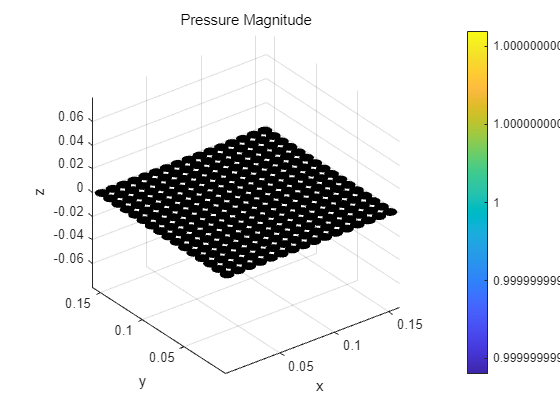

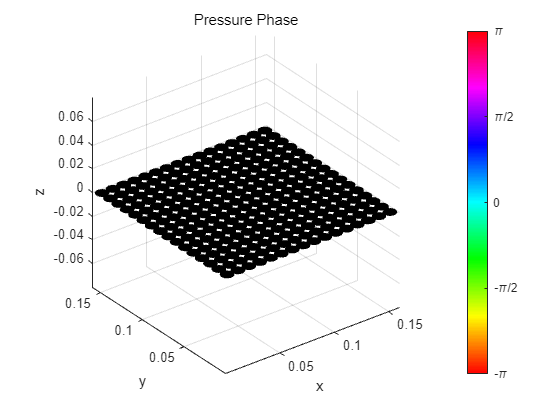

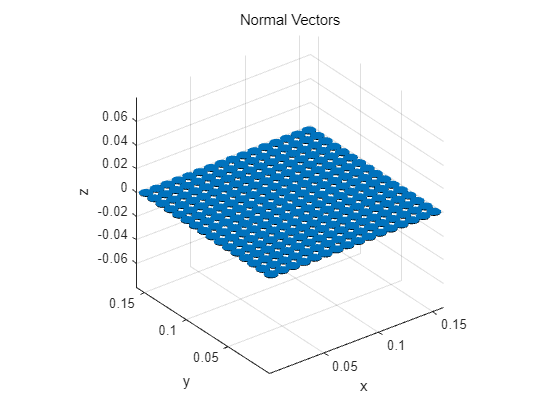


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:16
    for j = 1:16
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        transducer_info.Phase = -phases(i,j);
        % transducer_info.Phase = 0;
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]

## Simulation Space

reading_pos_x = 0e-3 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_y = 0e-3 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.5e-3 : 160e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.08, reading_pos_z);

Started at 2024-10-11 20:28:28
Finished at 2024-10-11 20:47:29
Progressed time : 00:19:01


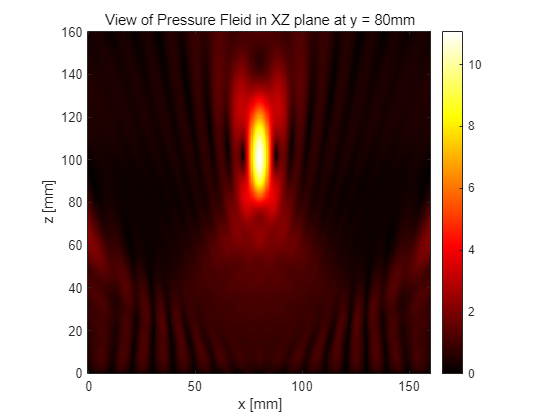


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));
Pressure_dxyz_i_rot = rot90(Pressure_dxyz_i, -1);

figure;imagesc(reading_pos_x.*1e3, reading_pos_z.*1e3, Pressure_dxyz_i_rot);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top', 'YDir', 'normal');
title('View of Pressure Fleid in XZ plane at y = 80mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('z [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 11.0865

% row_data = Pressure_dxyz_i(49, :);
% plot(row_data);
% xlabel('Z-index');
% ylabel('Gain');
% title('Gain graph at Center');
% grid on;

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.1);

Started at 2024-10-11 20:47:31
Finished at 2024-10-11 21:07:13
Progressed time : 00:19:42


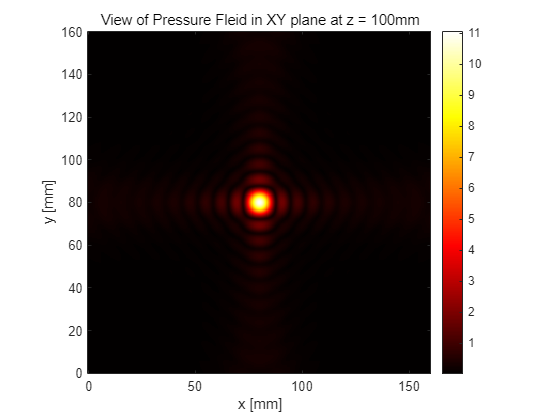


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top','YDir', 'normal');
title('View of Pressure Fleid in XY plane at z = 100mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('y [mm]');